A = 865×865×3 uint8 数组
A(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   249   255   250   255   249   250   240   250   255   197   189   205   171   100   104   114   115    94    29    17     5    35     6     0    15     0    41    70    75    64    49    92   154   149   159   175   181   185   187   181   177   169   178   166   225   224   220   223   214   208   201   201   206   205   189   170   177   168   143   151   146   148    94    91    79    88    72    15     3    12     1    26    27    23    17    53   126   131   128   123   187   220   208   213   224   245   246   244   25

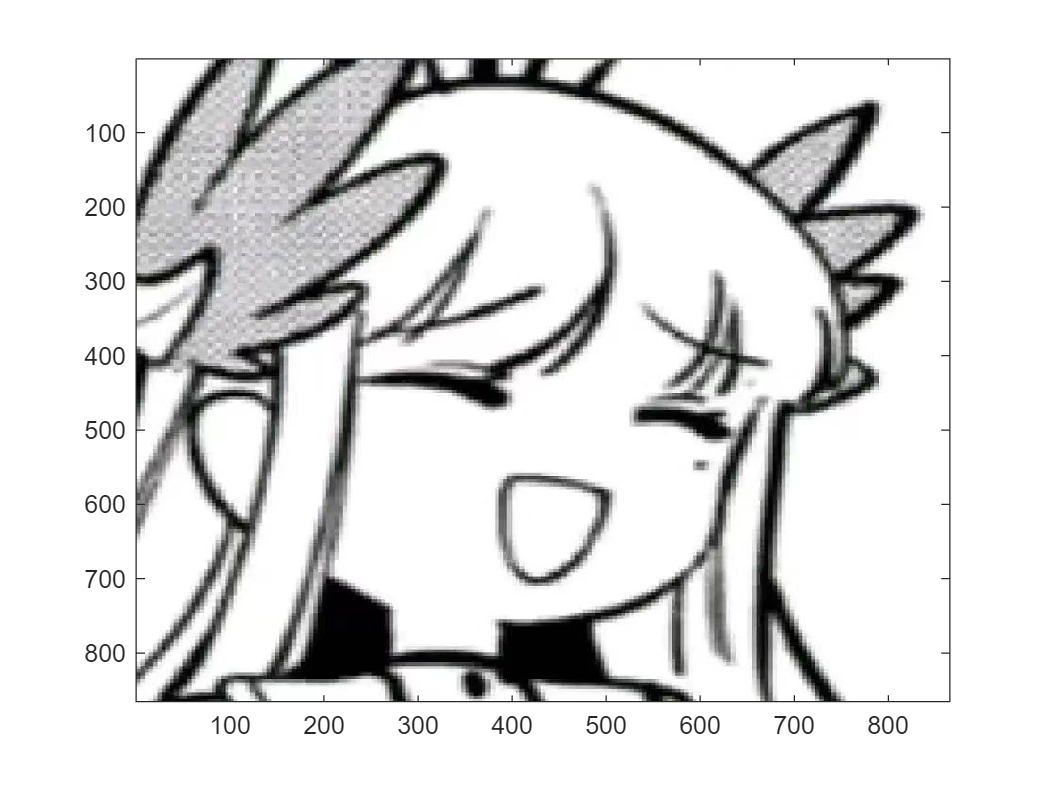

SunDay


   95.0100
   73.1100
   60.6800
   48.6000
   89.1300



MonDay


   76.2100
   45.6500
   41.8500
   82.1400
   44.4700



TuesDay


   61.5400
   79.1900
   92.1800
   73.8200
   57.6300



WednesDay


   40.5700
   93.5500
   91.6900
   41.0300
   89.3600



ThursDay


   55.7900
   75.2900
   81.3200
    0.9900
   13.8900



FriDay


   70.2800
   69.8700
   90.3800
   67.2200
   19.8800



SaturDay


   81.5300
   74.6800
   74.5100
   93.1800
   46.6000



A = 1×1 cell 数组
    {'Mathematics is simple'}


% A = importdata(filename) 从filename表示的文件中将数据加载到数组A中。

A = importdata("import_test.jpg")
image(A)

% A = importdata(___, delimiterIn, headerlinesIn)
%  从ASCII文件，文件名或剪贴板中加载数据，并从行headerlinesIn + 1开始读取数字数据。
filename = 'weeklydata.txt';
delimiterIn = ' '; % 分隔符 指的是txt文件中的数据通过它分隔
headerlinesIn = 1; % 指定文件开头需要跳过的行数（通常是标题行）
A = importdata(filename,delimiterIn,headerlinesIn);

% View data
for k = [1:7]
   disp(A.colheaders{1, k})
   disp(A.data(:, k))
   disp(' ')
end

% A = importdata('-pastespecial')
% 从系统剪贴板而不是文件加载数据。
A = importdata('-pastespecial')

% fgetl     从文件中读取行，删除换行符
% fgets	    从文件中读取行，保留换行符
% fopen	    打开文件，或获取有关打开文件的信息
% fprintf	将数据写入文本文件
% fread	    从二进制文件读取数据

filename = 'myfile.txt';
rows = 7;
cols = 5;

% 打开文件
fid = fopen(filename);

% 修正1: 简化文件头读取（跳过前2行）
for k = 1:3
    fgetl(fid);  % 跳过"Rainfall Data"和"Months:..."
end

% 修正2: 灵活读取M值（允许空格）
M_line = fgetl(fid);  % 读取"M = 3"整行
M = sscanf(M_line, 'M = %d');

% 修正3: 读取并转置矩阵 + 跳过中间空行
for n = 1:M
    % 读取时间/月份
    mydata(n).time = fscanf(fid, '%s', 1);
    mydata(n).month = fscanf(fid, '%s', 1);

    mydata(n).raindata = fscanf(fid, '%f', [rows, cols]); % 读成7×5 还是列优先
    
    % 跳过可能的尾部空行
    fgetl(fid); 
end

% 显示结果
for n = 1:M
   fprintf('Time: %s\nMonth: %s\nData:\n', ...
           mydata(n).time, mydata(n).month);
   disp(mydata(n).raindata)
end

Time: 12:00:00
Month: June-2012
Data:


   17.2100   17.5700   11.0900   13.1700   14.4500
   28.5200       NaN    9.5900       NaN   14.0000
   39.7800   12.0100    9.3300   14.8900   18.2300
   16.5500   17.9200       NaN   19.3300   10.3400
   23.6700   28.4900    0.3100   20.9700   17.9500
   19.1500   17.4000    0.2300   19.5000   16.4600
    0.3500   17.0600   10.4600   17.6500   19.3400



Time: 09:10:02
Month: July-2012
Data:


   12.7600       NaN   34.0000   33.1700   24.4500
   16.9400   24.8900   18.2300       NaN   34.0000
   14.3800   19.3300   30.3400   34.8900   28.6700
   11.8600   30.9700   27.9500   29.3300   30.3400
   16.8900   49.5000   16.4600   30.9700   27.9500
   20.4600   47.6500   19.3400   49.5000   36.4600
   23.1700   24.4500   30.4600   47.6500   29.3400



Time: 15:03:40
Month: August-2012
Data:


   17.0900   13.4800   27.2100   11.4500   25.0500
   16.5500   22.5500   26.7900   13.4800   27.2100
   19.5900   24.0100   24.9800   22.5500   26.7900
   17.2500       NaN   12.2300   24.0100   24.9800
   19.2200   21.1900   16.9900       NaN   12.2300
   17.5400   25.8500   18.6700   21.1900   16.9900
   11.4500   25.0500   17.5400   25.8500   18.6700




% 关闭文件
fclose(fid);